% Setup
format compact
clearvars
clc

% Variables
SampleOut = load('./Data/NoiseTest.mat', 'SampleOut');
SampleOut = SampleOut.SampleOut;

Sep = [12000, 46500, 51000, 60500, 63000, 67000, 69000, length(SampleOut)-500];

Fs = 6000/30; % Sampling Freq

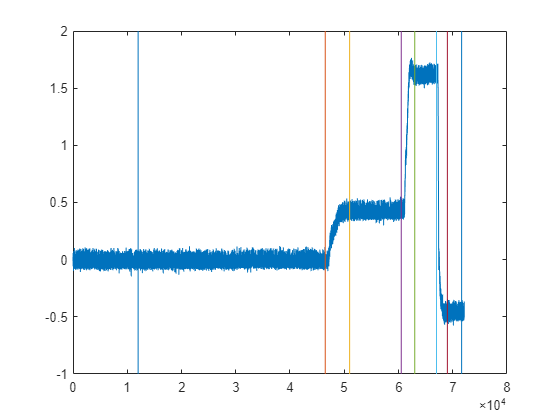

% Plot
figure();
plot(SampleOut);
hold on;
line(repmat(Sep, 2, 1), repmat(ylim', 1, length(Sep)));
hold off;

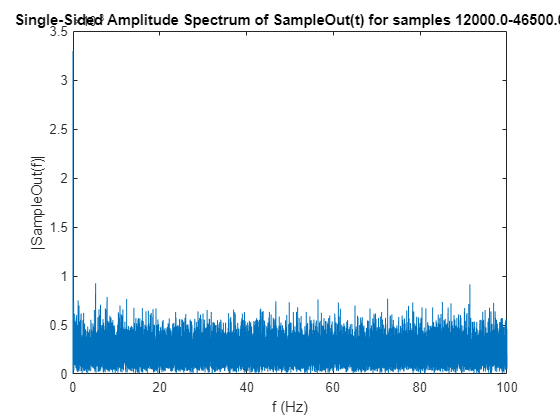

Top 3 frequencies: 0.0 0.0 0.0

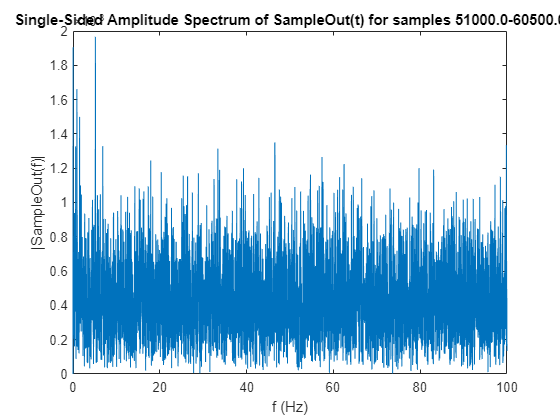

Top 3 frequencies: 5.2 0.0 5.2

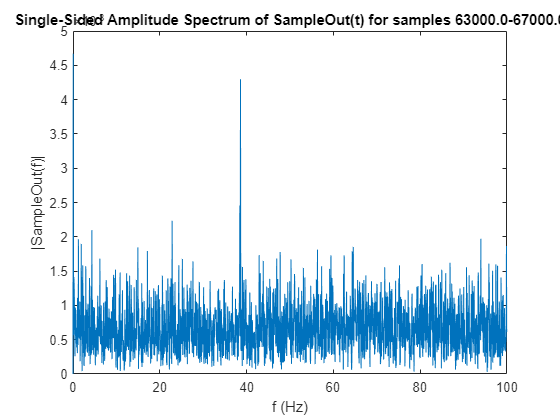

Top 3 frequencies: 0.0 38.6 38.4

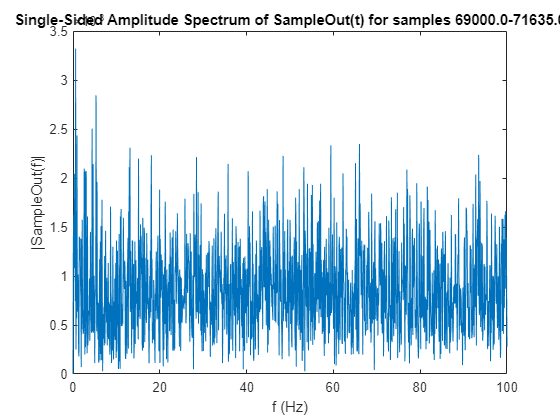

Top 3 frequencies: 0.6 5.3 4.4

% Fourier

for i = 1:2:length(Sep)
    YData = SampleOut(Sep(i):Sep(i+1));
    YData = YData - mean(YData);
    L = length(YData);
    Y = fft(YData);
    P2 = abs(Y/L);
    P1 = P2(1:(fix(L/2)+1));
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    figure();
    plot(f,P1);
    title(sprintf('Single-Sided Amplitude Spectrum of SampleOut(t) for samples %.1f-%.1f', Sep(i), Sep(i+1)));
    xlabel('f (Hz)');
    ylabel('|SampleOut(f)|');
    [~,max3freqInd]=maxk(P1,3);
    fprintf('Top 3 frequencies: %.1f %.1f %.1f', f(max3freqInd))
end